clear all
n = 1000000;
tic
for i = 1:n
    squares(i) = i^2;
end
toc

Elapsed time is 6.317173 seconds.


squares(end)

ans = 1.0000e+12

size(squares)

ans =            1     1000000


clear all
n = 1000000;
squares = zeros(n,1);
tic
for i = 1:n
    squares(i) = i^2;
end
toc

Elapsed time is 5.915595 seconds.


tic
numbers = 1:n;
squares = numbers .^ 2;
toc

Elapsed time is 0.057014 seconds.


tic 
squares = (1:n).^2;
toc

Elapsed time is 0.060131 seconds.


sin(pi)

ans = 1.2246e-16

sin(numbers)

ans =     0.8415    0.9093    0.1411   -0.7568   -0.9589   -0.2794    0.6570    0.9894    0.4121   -0.5440   -1.0000   -0.5366    0.4202    0.9906    0.6503   -0.2879   -0.9614   -0.7510    0.1499    0.9129    0.8367   -0.0089   -0.8462   -0.9056   -0.1324    0.7626    0.9564    0.2709   -0.6636   -0.9880   -0.4040    0.5514    0.9999    0.5291   -0.4282   -0.9918   -0.6435    0.2964    0.9638    0.7451   -0.1586   -0.9165   -0.8318    0.0177    0.8509    0.9018    0.1236   -0.7683   -0.9538   -0.2624


x = 0:0.01:2*pi

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


x = linspace(0,2*pi,1000);
y = sin(x);

x = linspace(0,2*pi,100000);
y = sin(x);
tic 
for i=1:length(y)
    if y(i)>0.5
        y(i)=0.5;
    end
end
toc

Elapsed time is 0.984992 seconds.


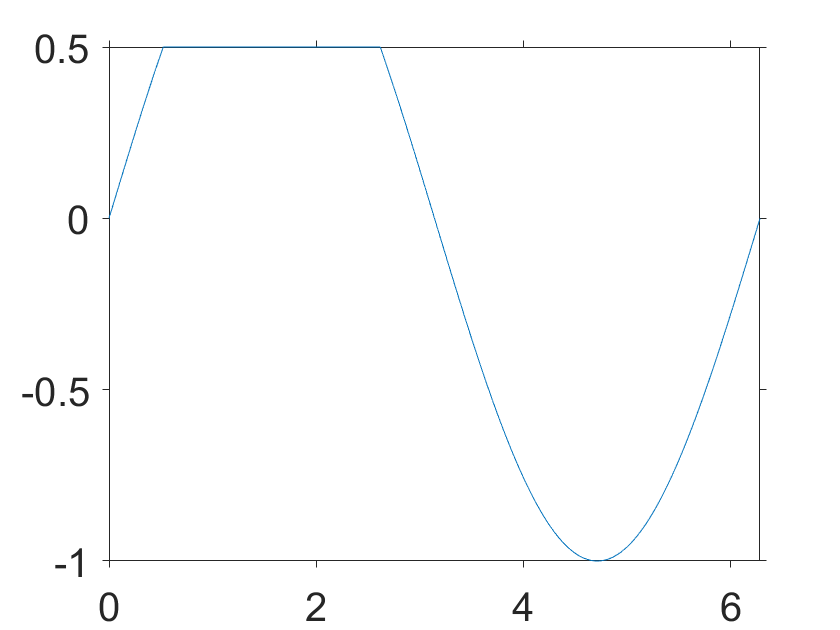

plot(x,y)

x = linspace(0,2*pi,100000);
y = sin(x);
tic 
ind = find(y>0.5);
y(ind) = 0.5;
toc

Elapsed time is 0.017724 seconds.


plot(x,y)

y>0.2

ans = 1×100000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


x = linspace(0,2*pi,100000);
y = sin(x);
tic 
y( y>0.5 ) = 0.5;
y(y<-0.5) = -0.5;
toc

Elapsed time is 0.051027 seconds.


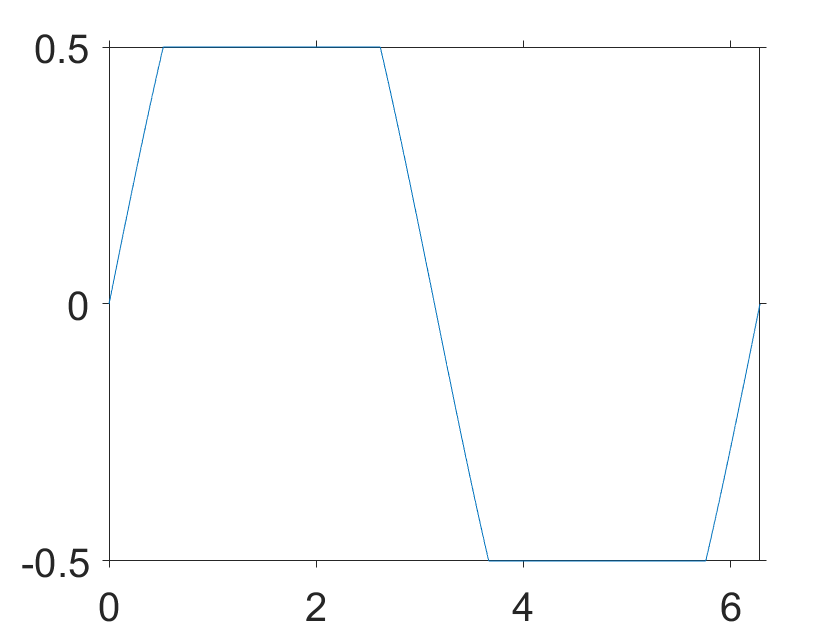

plot(x,y)